# EDUCAT database visualization

TIP: when getting new data or new connection --> right click on white space and choose " clear all Output" 

clear all Output
clc
close all
username = "analyst";
userInput = ' password: ';
password = input(userInput,'s');

import classes.measurement
import classes.instrument
import classes.data
m = measurement(username,password);
clc;
clear password userInput username;

 
m.list

ans = 26×6 table
    id                  description                       start_time               end_time          count        max    
    __    _______________________________________    ____________________    ____________________    _____    ___________

    87    'KUL cycle counter debug 15 [DELETE]'      18-Oct-2019 11:30:25    18-Oct-2019 11:30:32     353             353
    86    'KUL cycle counter debug 14 [DELETE]'      18-Oct-2019 11:28:45    18-Oct-2019 11:29:00     737             737
    85    'KUL cycle counter debug 13 [DELETE]'      18-Oct-2019 11:24:36    18-Oct-2019 11:24:44     401             401
    84    'KUL cycle counter debug 12 [DELETE]'      18-Oct-2019 11:07:28    18-Oct-2019 11:07:34       0     -2147483648
    83    'KUL cycle counter debug 11 [DELETE]

## Declaration of measurement

id= 71;
if( size(find(m.list.id == id),1)==1 && m.list.count(find(m.list.id == id,1)) > 2)
    disp('ID exists, running...')
    m=m.set_measurement_ID(id);
    m = m.declaration();
    % ******* get data ********
    m = m.get_dataset_DB();
    disp("done")
    duration = datetime(m.end_time, 'convertfrom','posixtime') - datetime(m.start_time, 'convertfrom','posixtime');
    disp(['duration: ' datestr(duration,'HH:MM:SS.FFF')])
elseif m.list.count(find(m.list.id == id,1)) < 2
    disp("measurement contains no data")
else
    disp("ID does not exist in database")
end

ID exists, running...


done


duration: 00:03:03.100


## Export data to workspaxe

m.exportData();

 

## Plot all measurement information

close all;
 
display(['Moment of measurement: ' datestr(datetime(m.start_time, 'convertfrom','posixtime'),'yyyy-mm-dd HH:MM:SS.FFF')]);

Moment of measurement: 2019-10-18 08:29:49.020


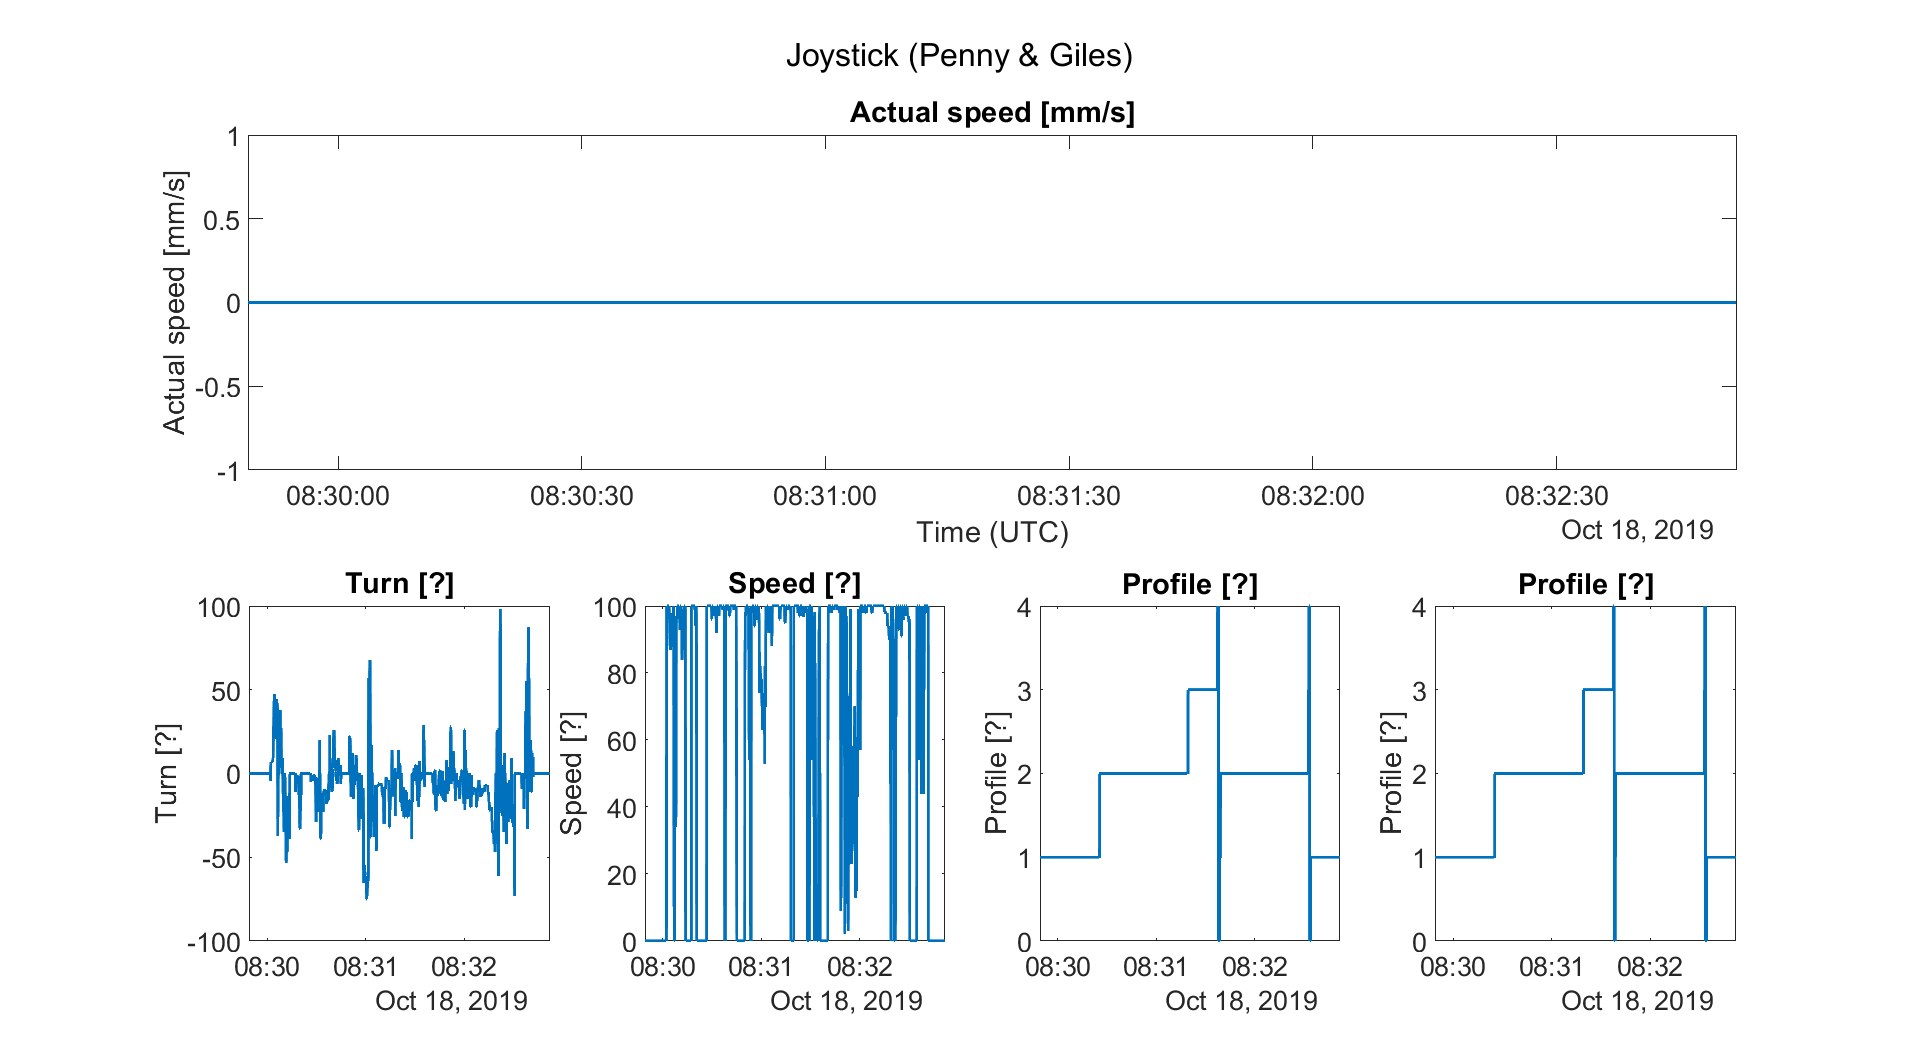

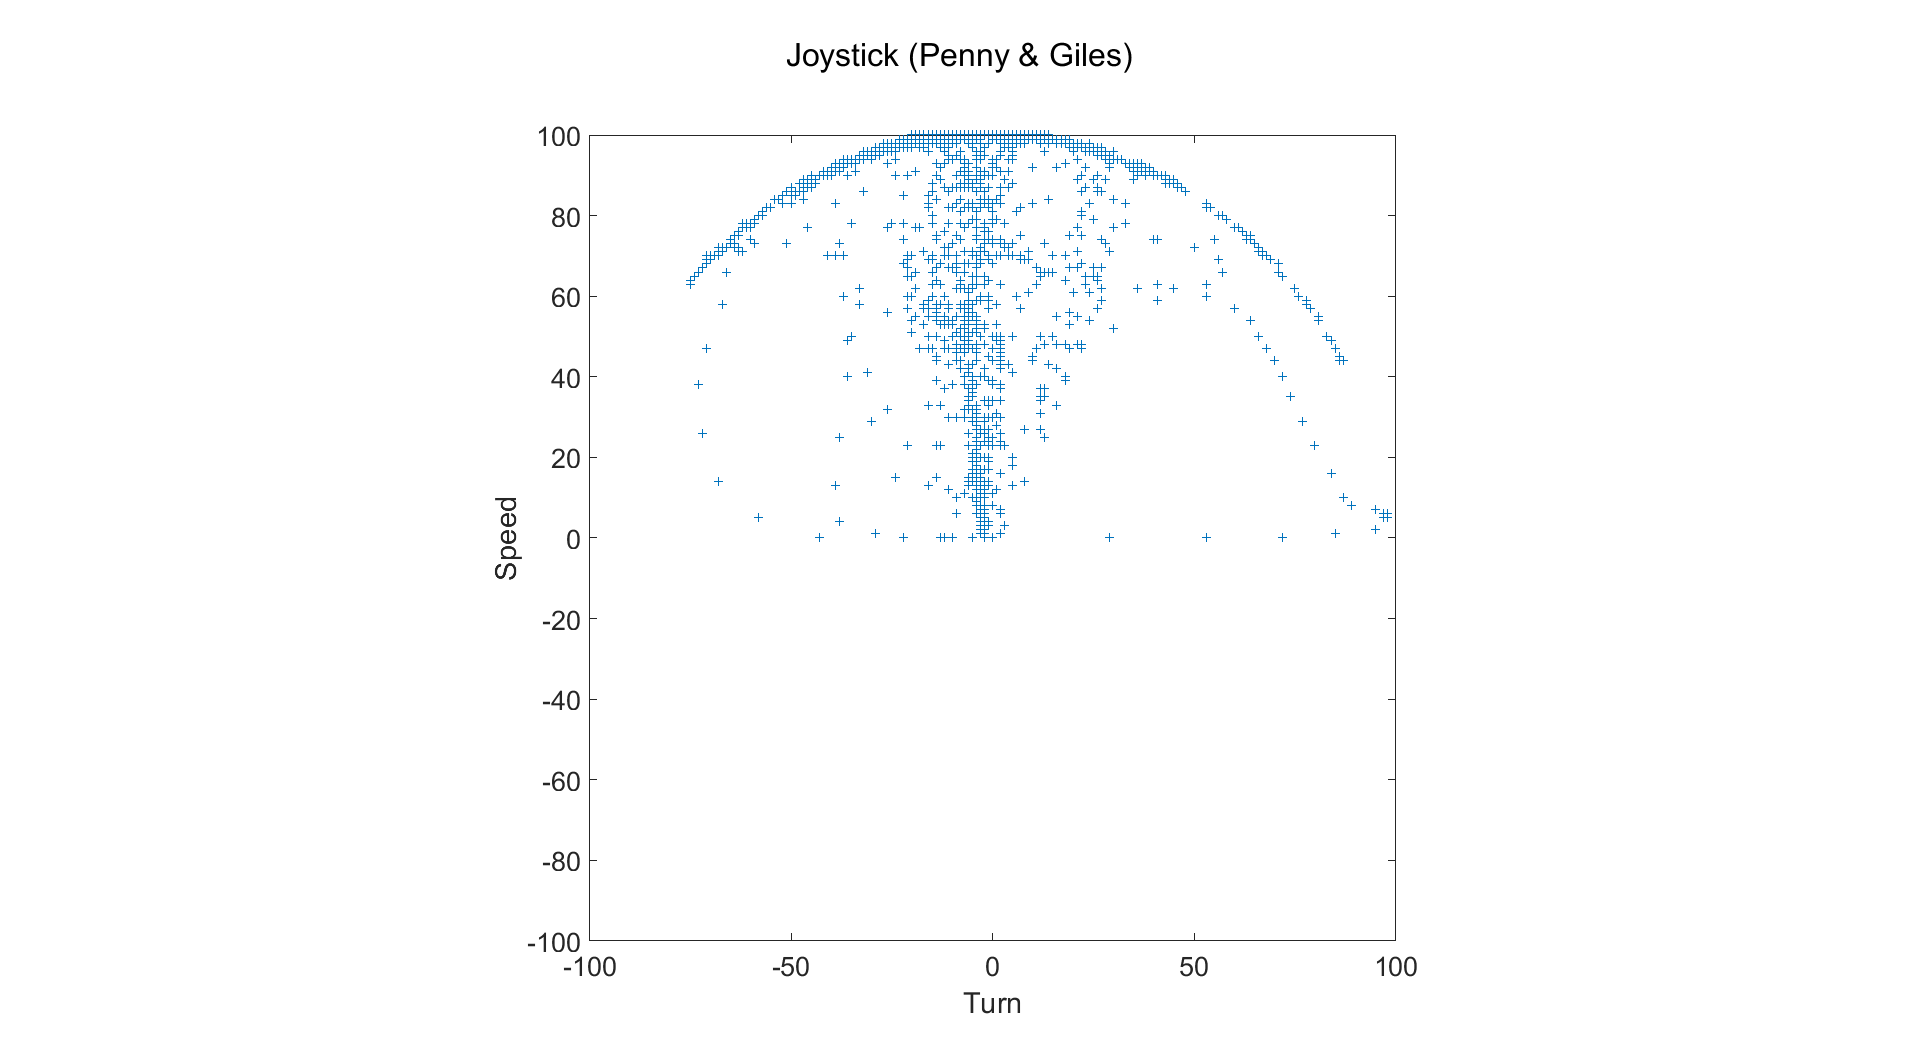

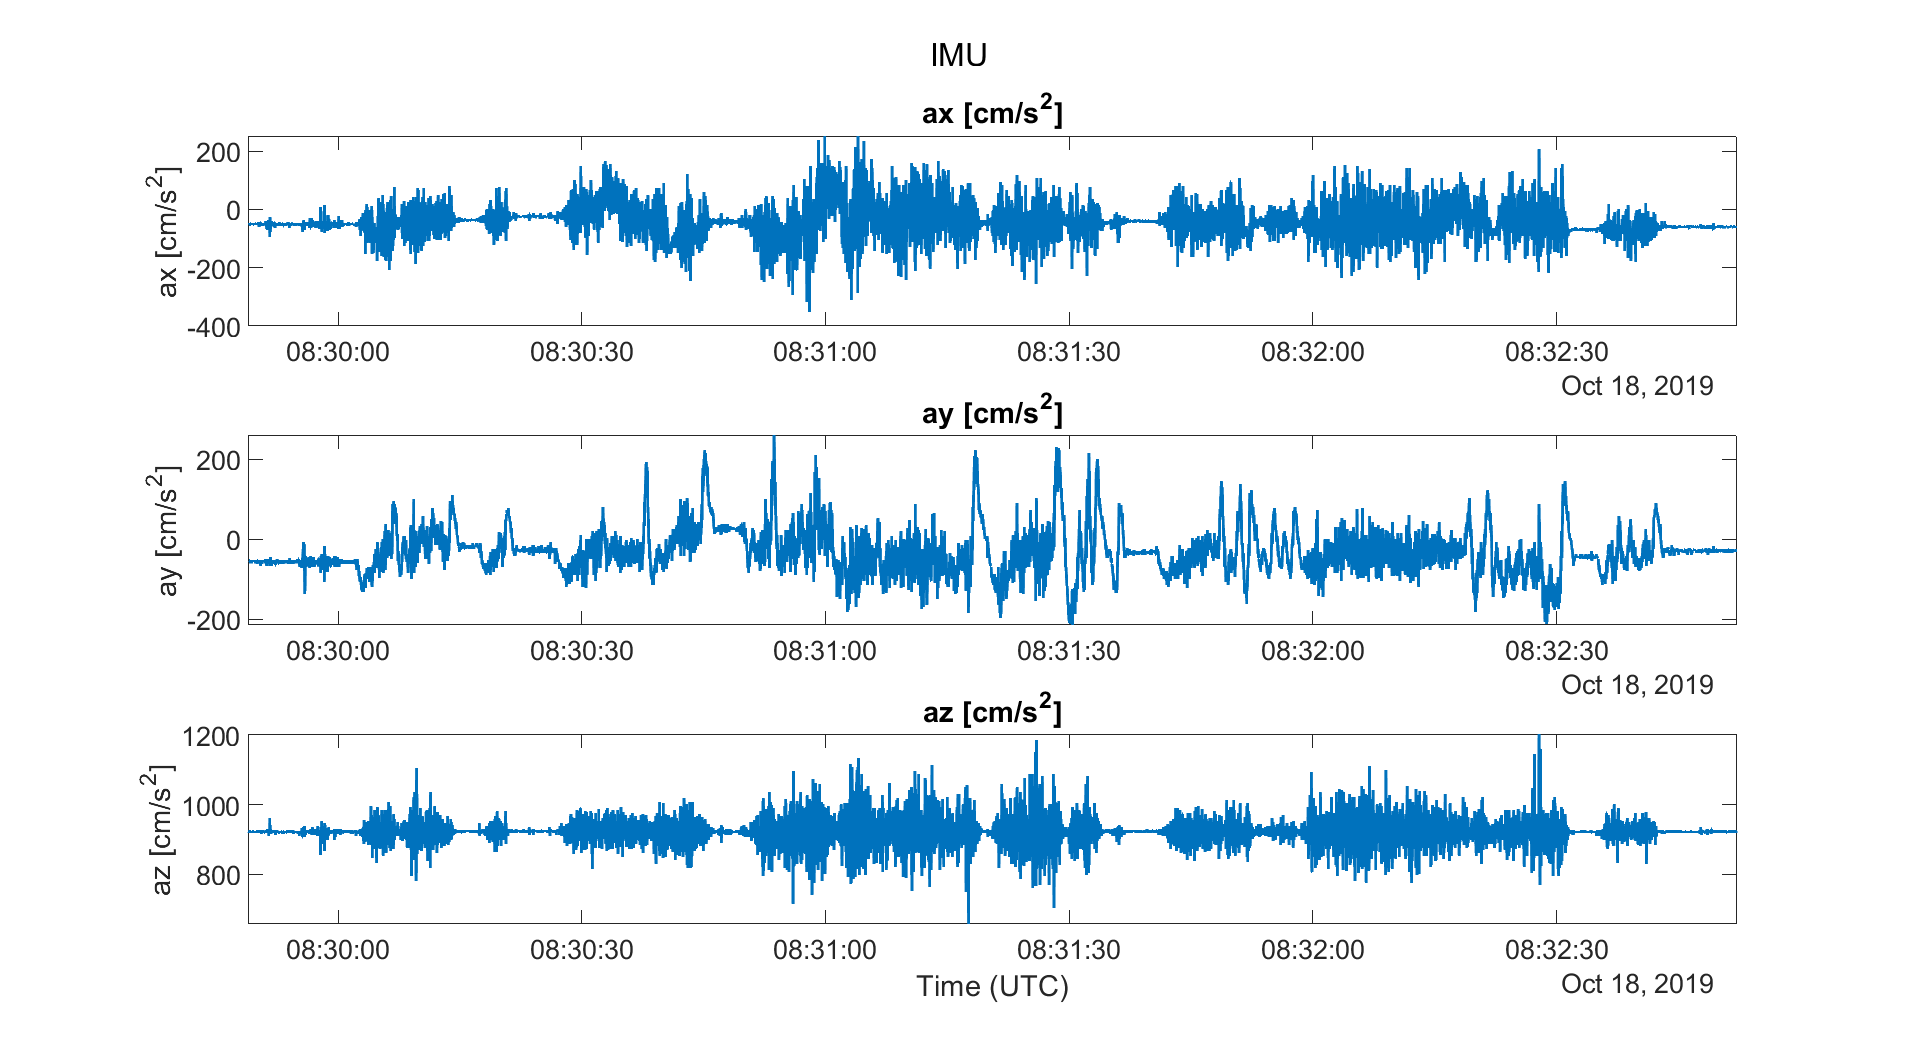

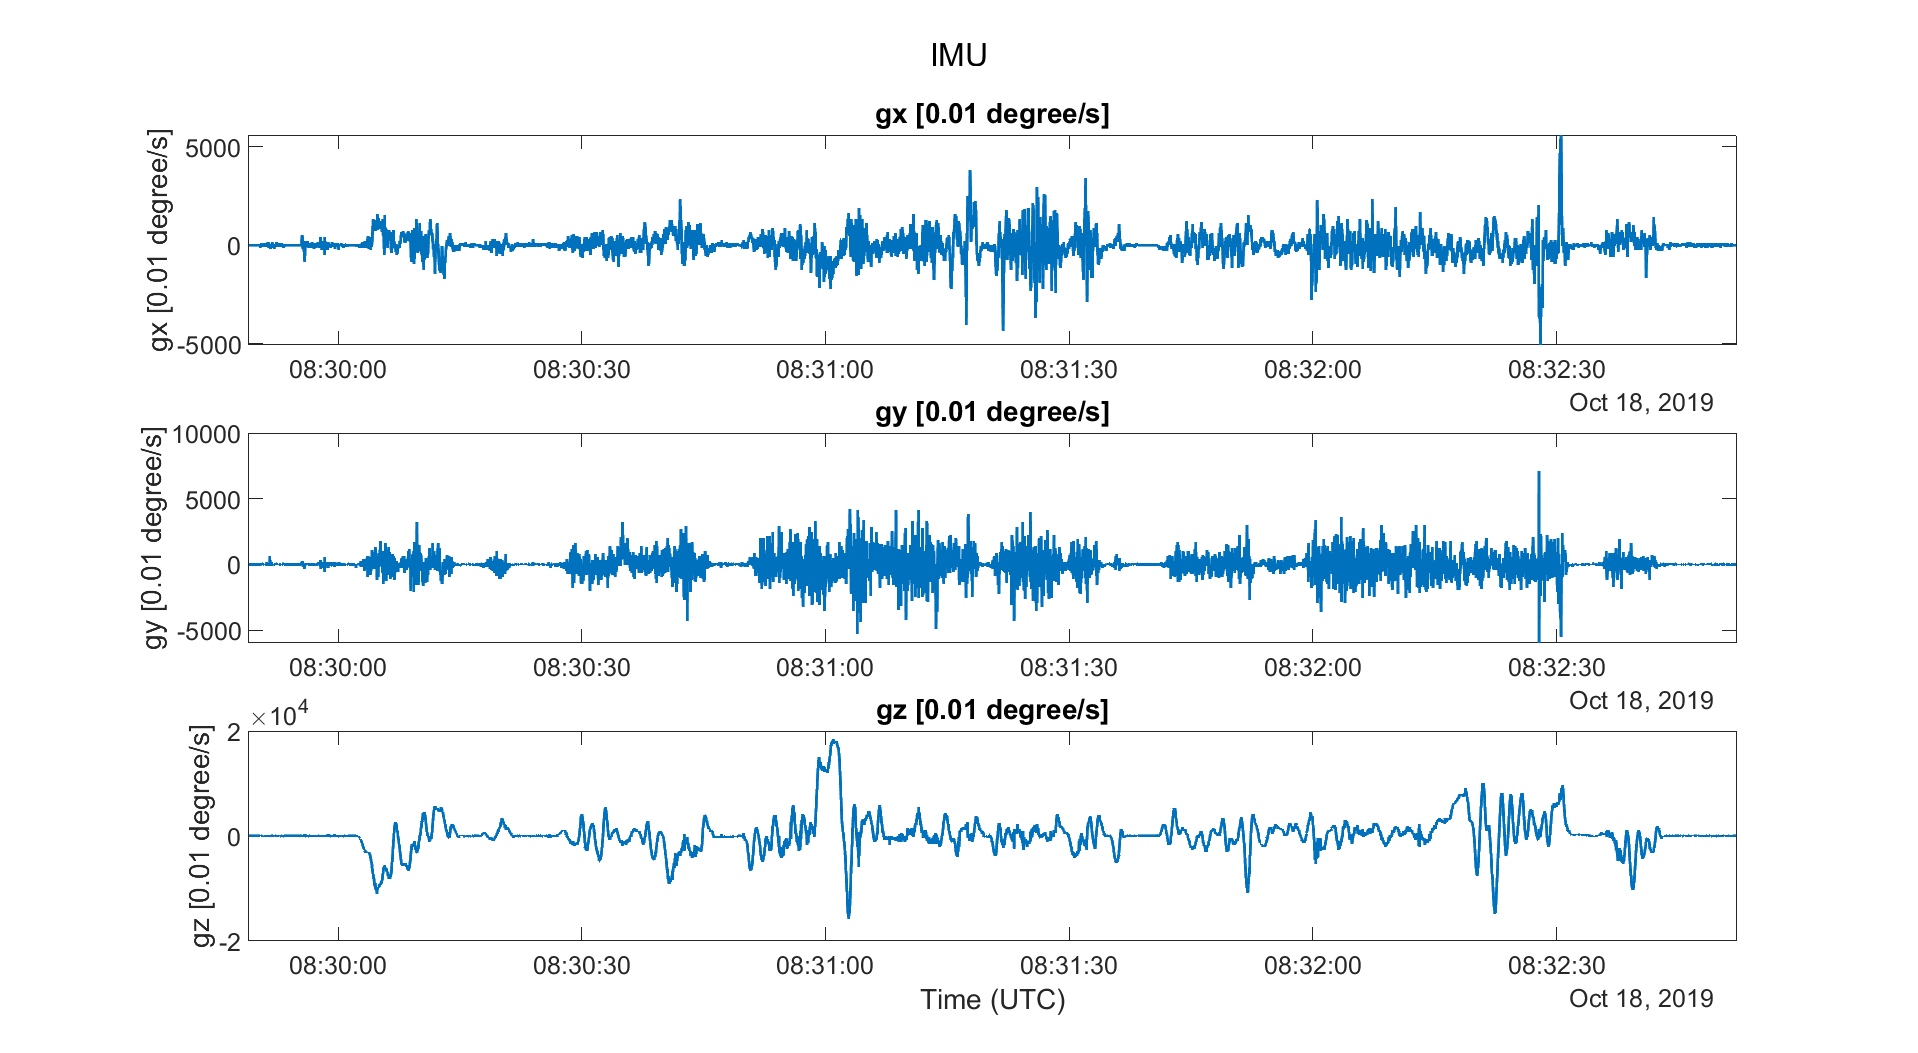

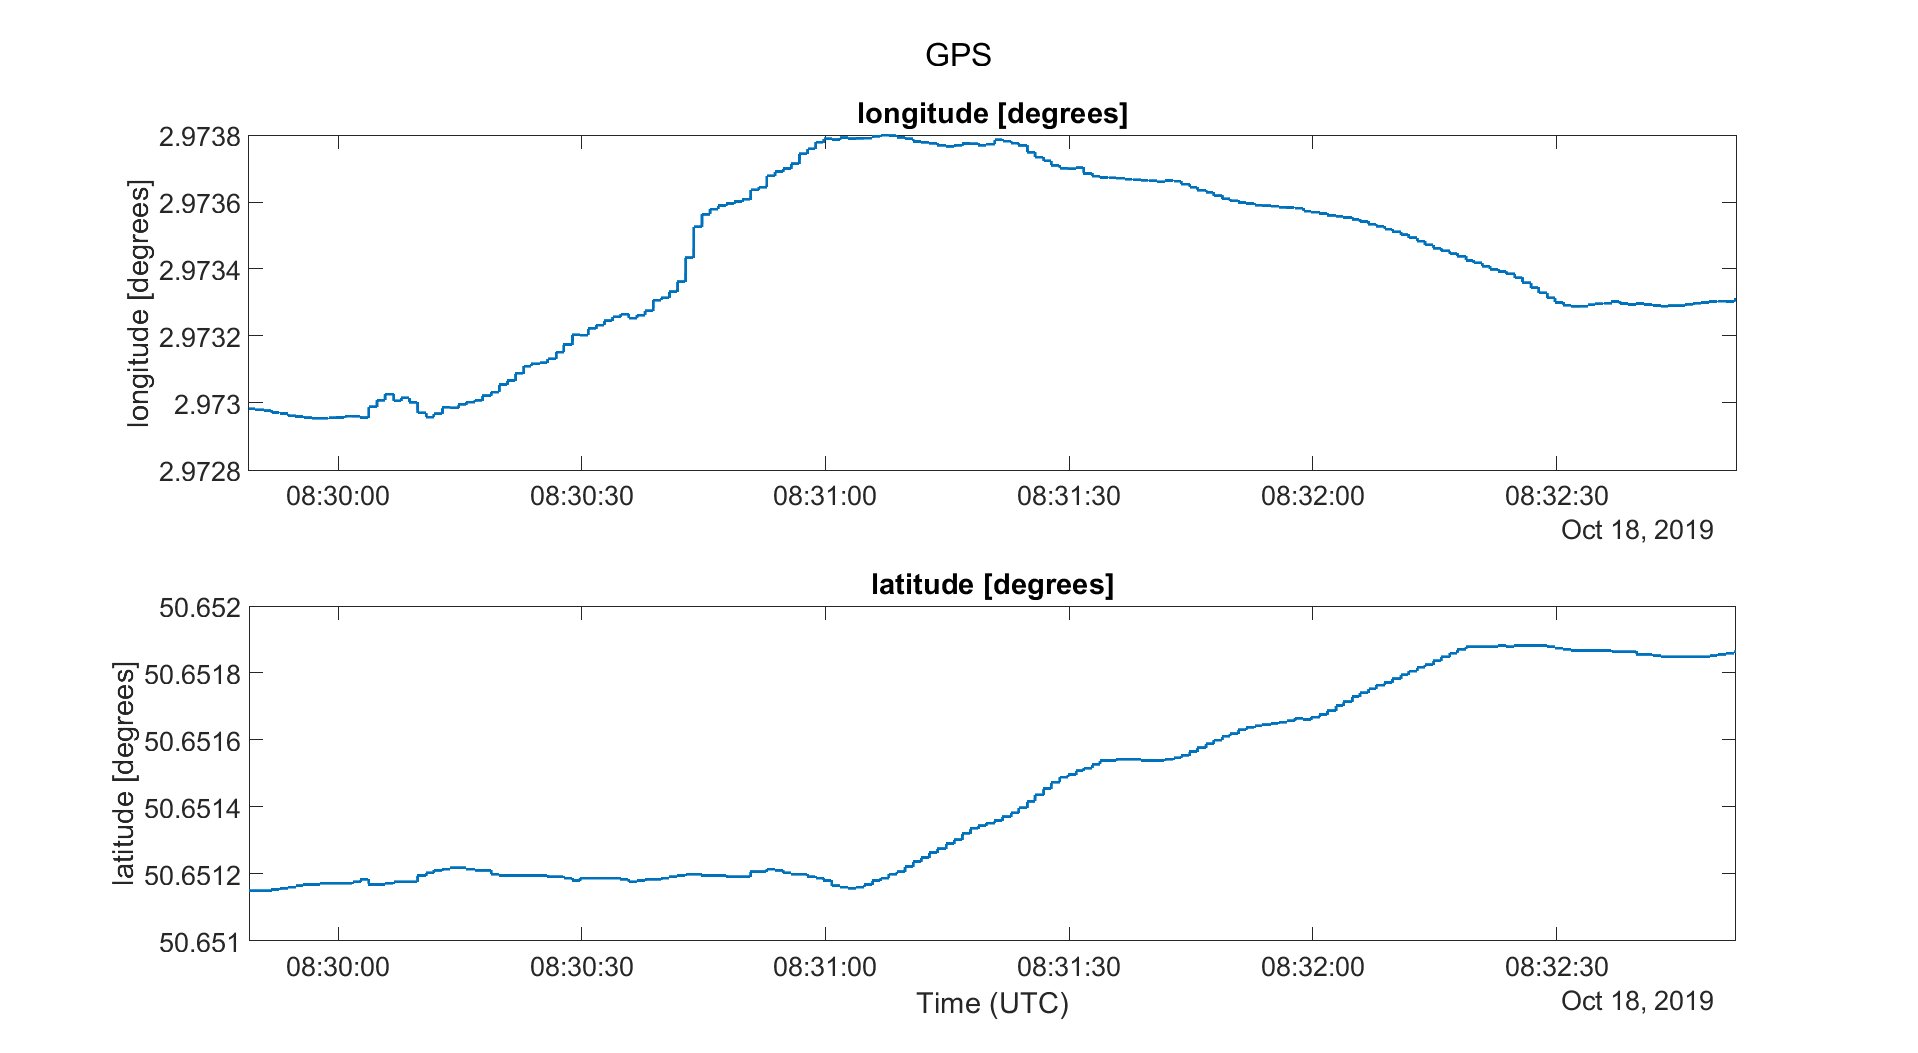

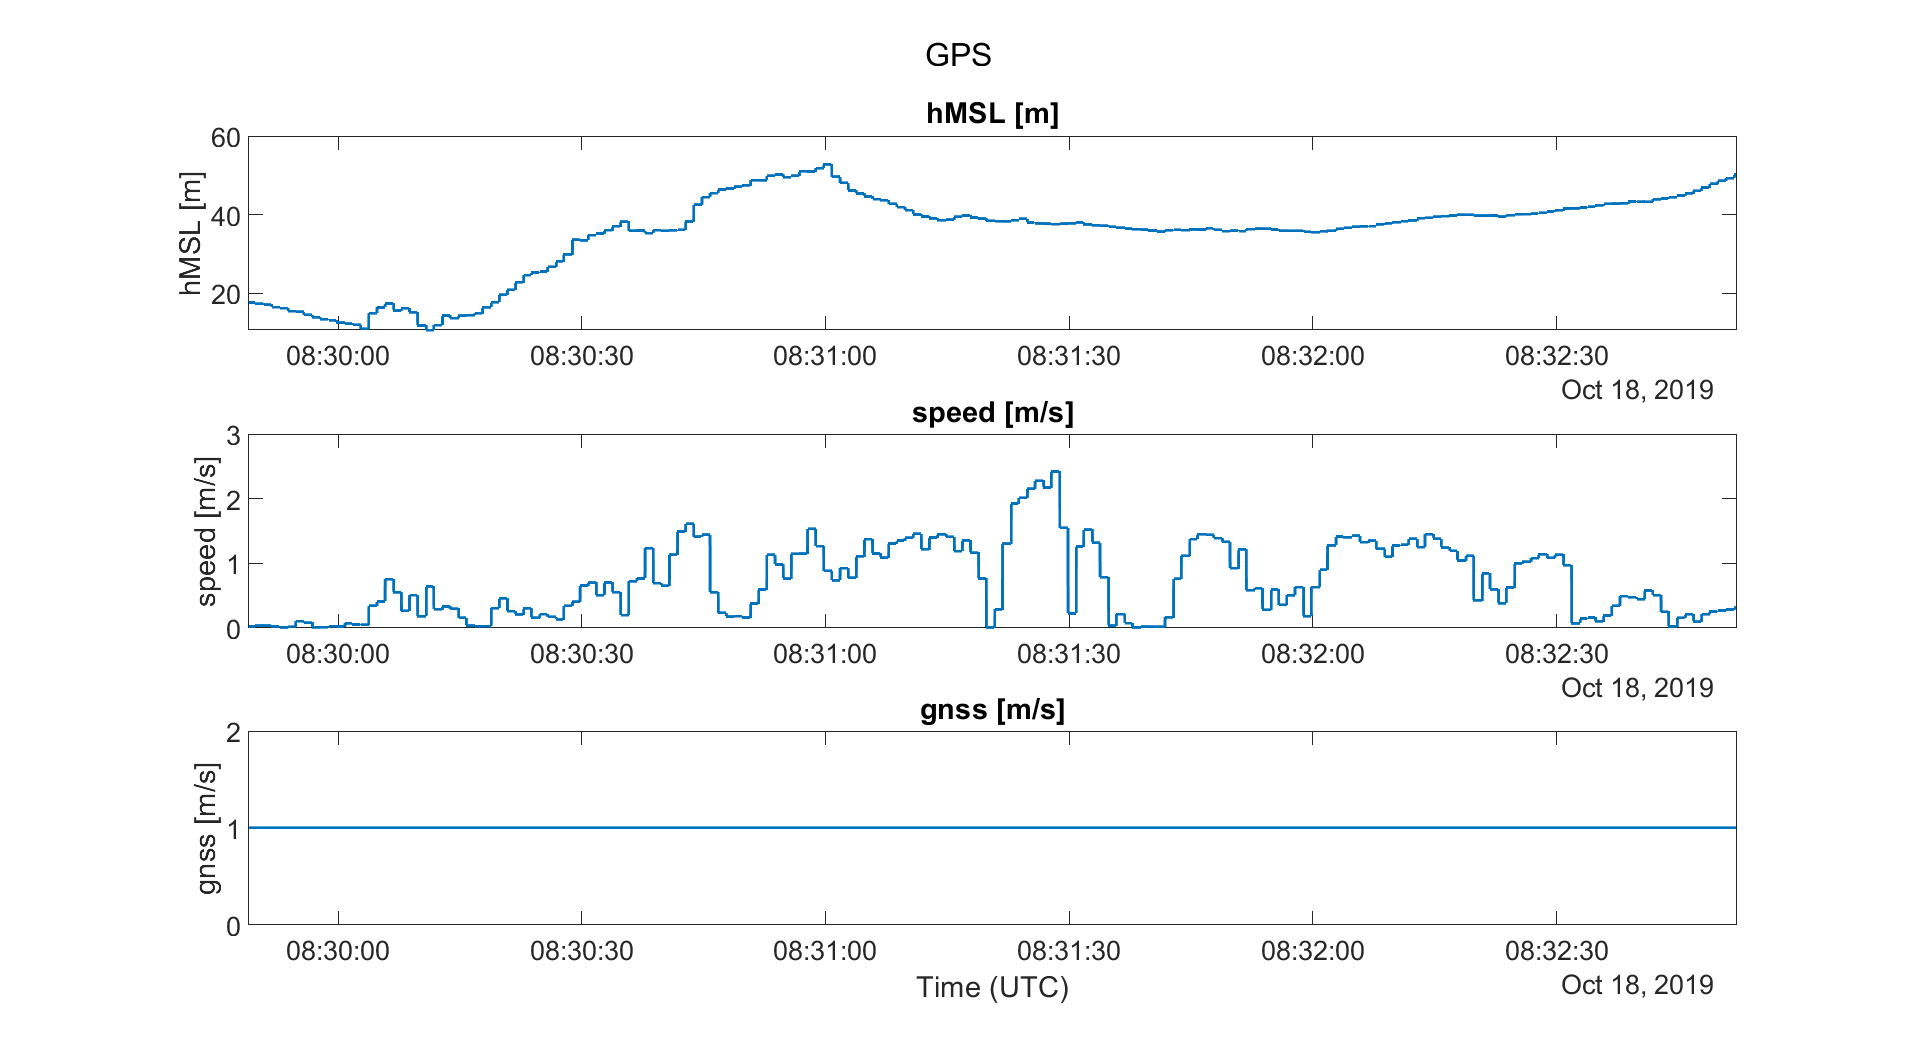

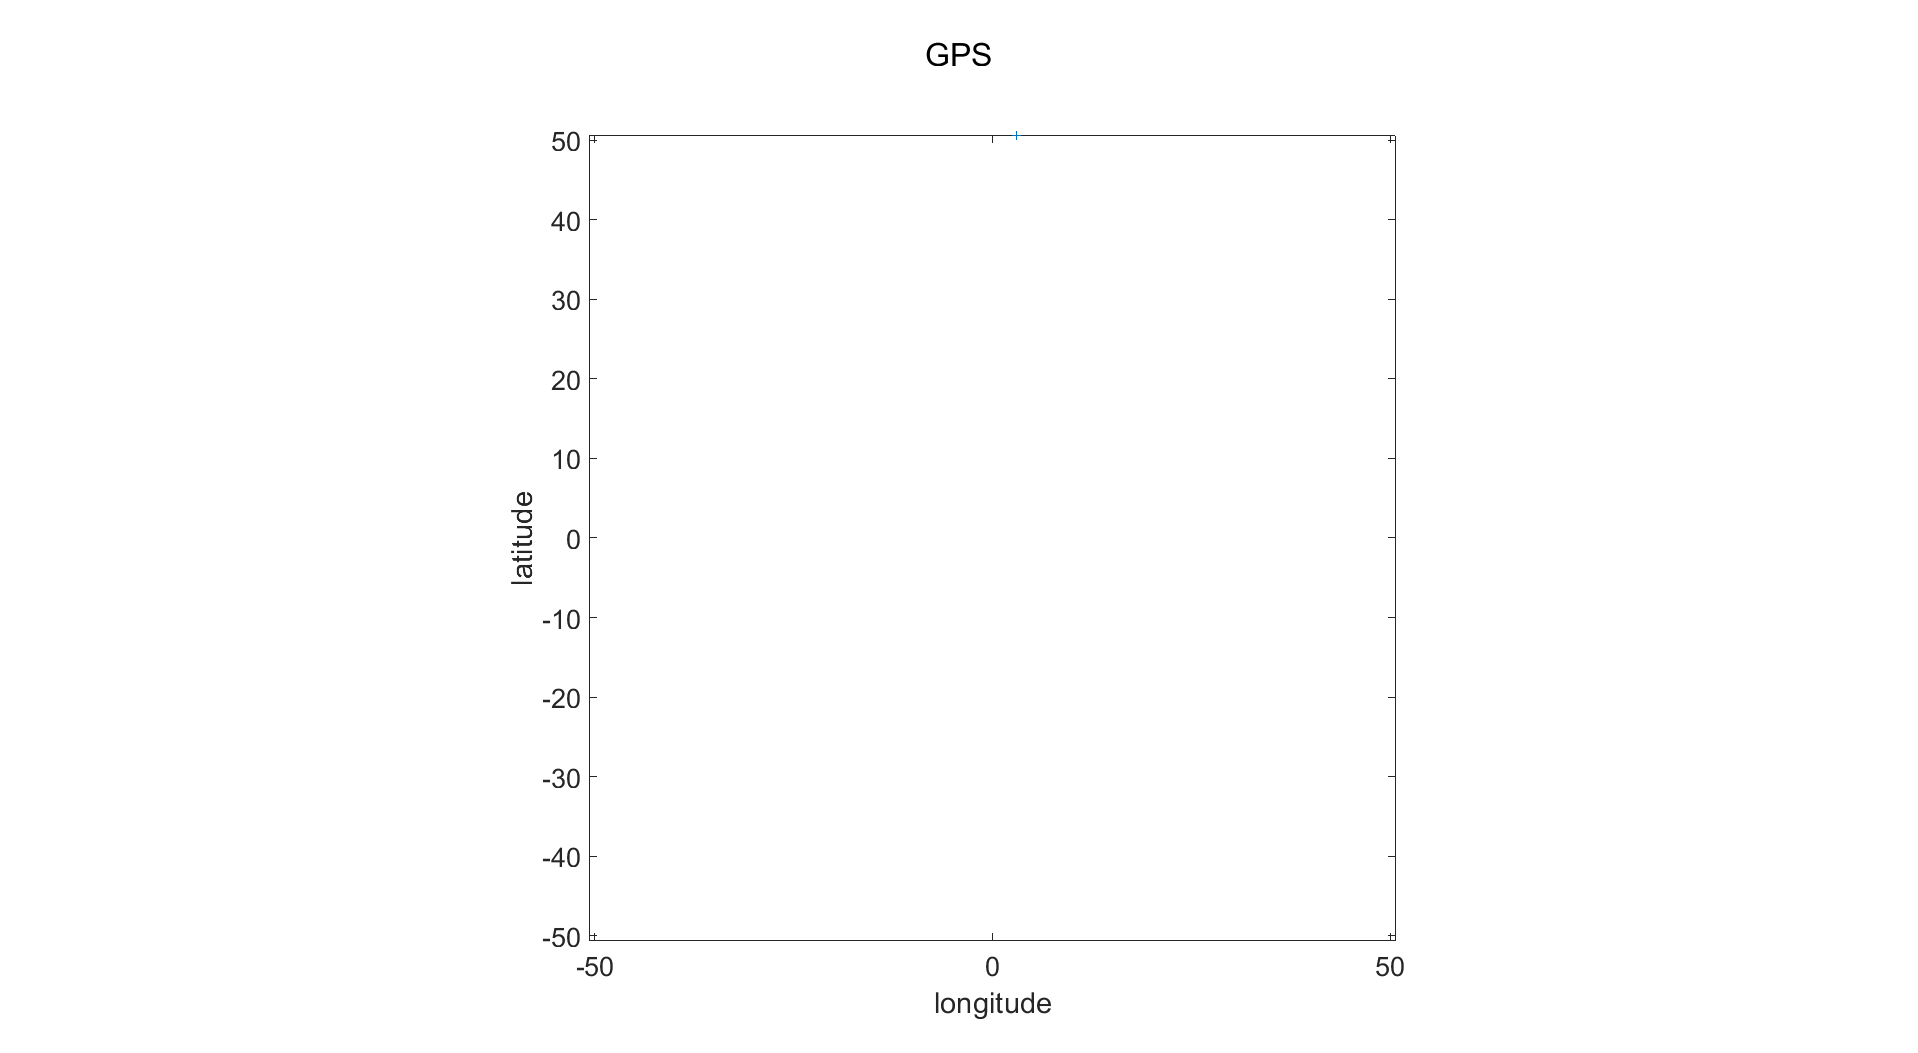

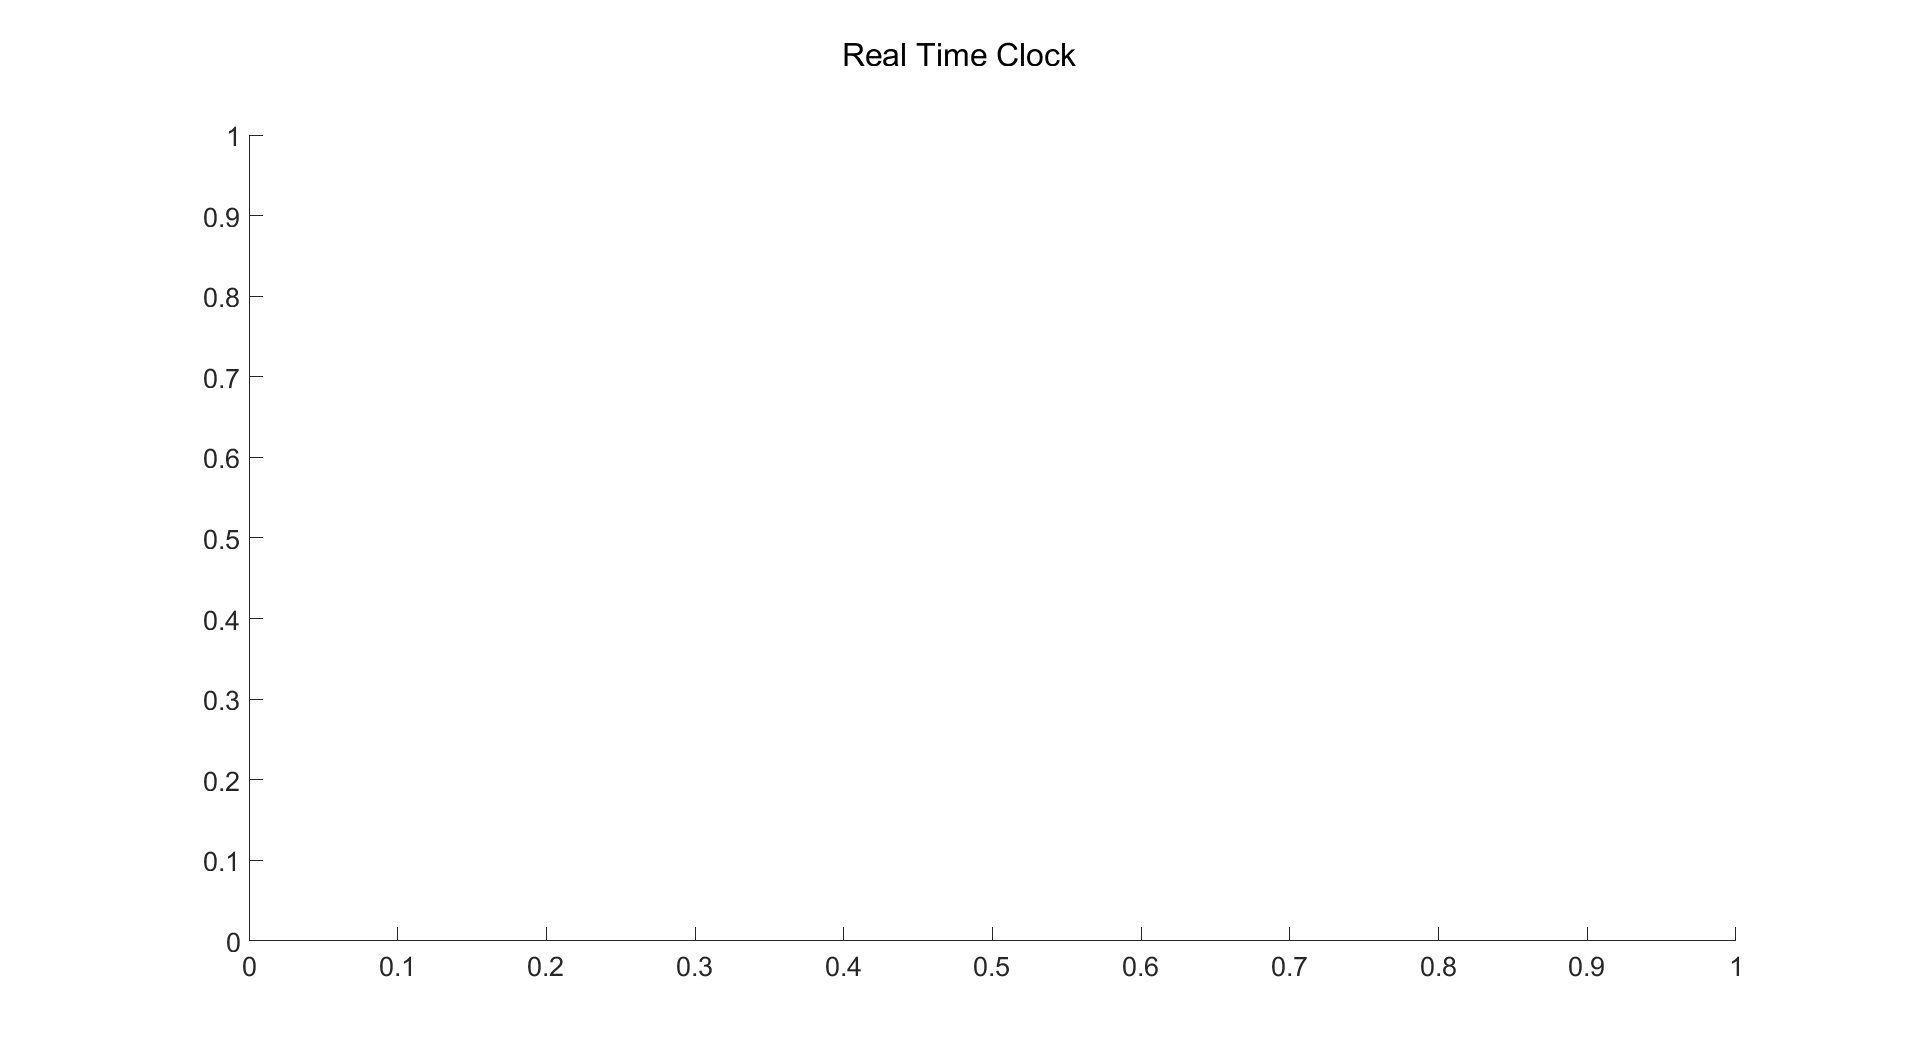

    "Real Time Clock"    " is not yet programmed"



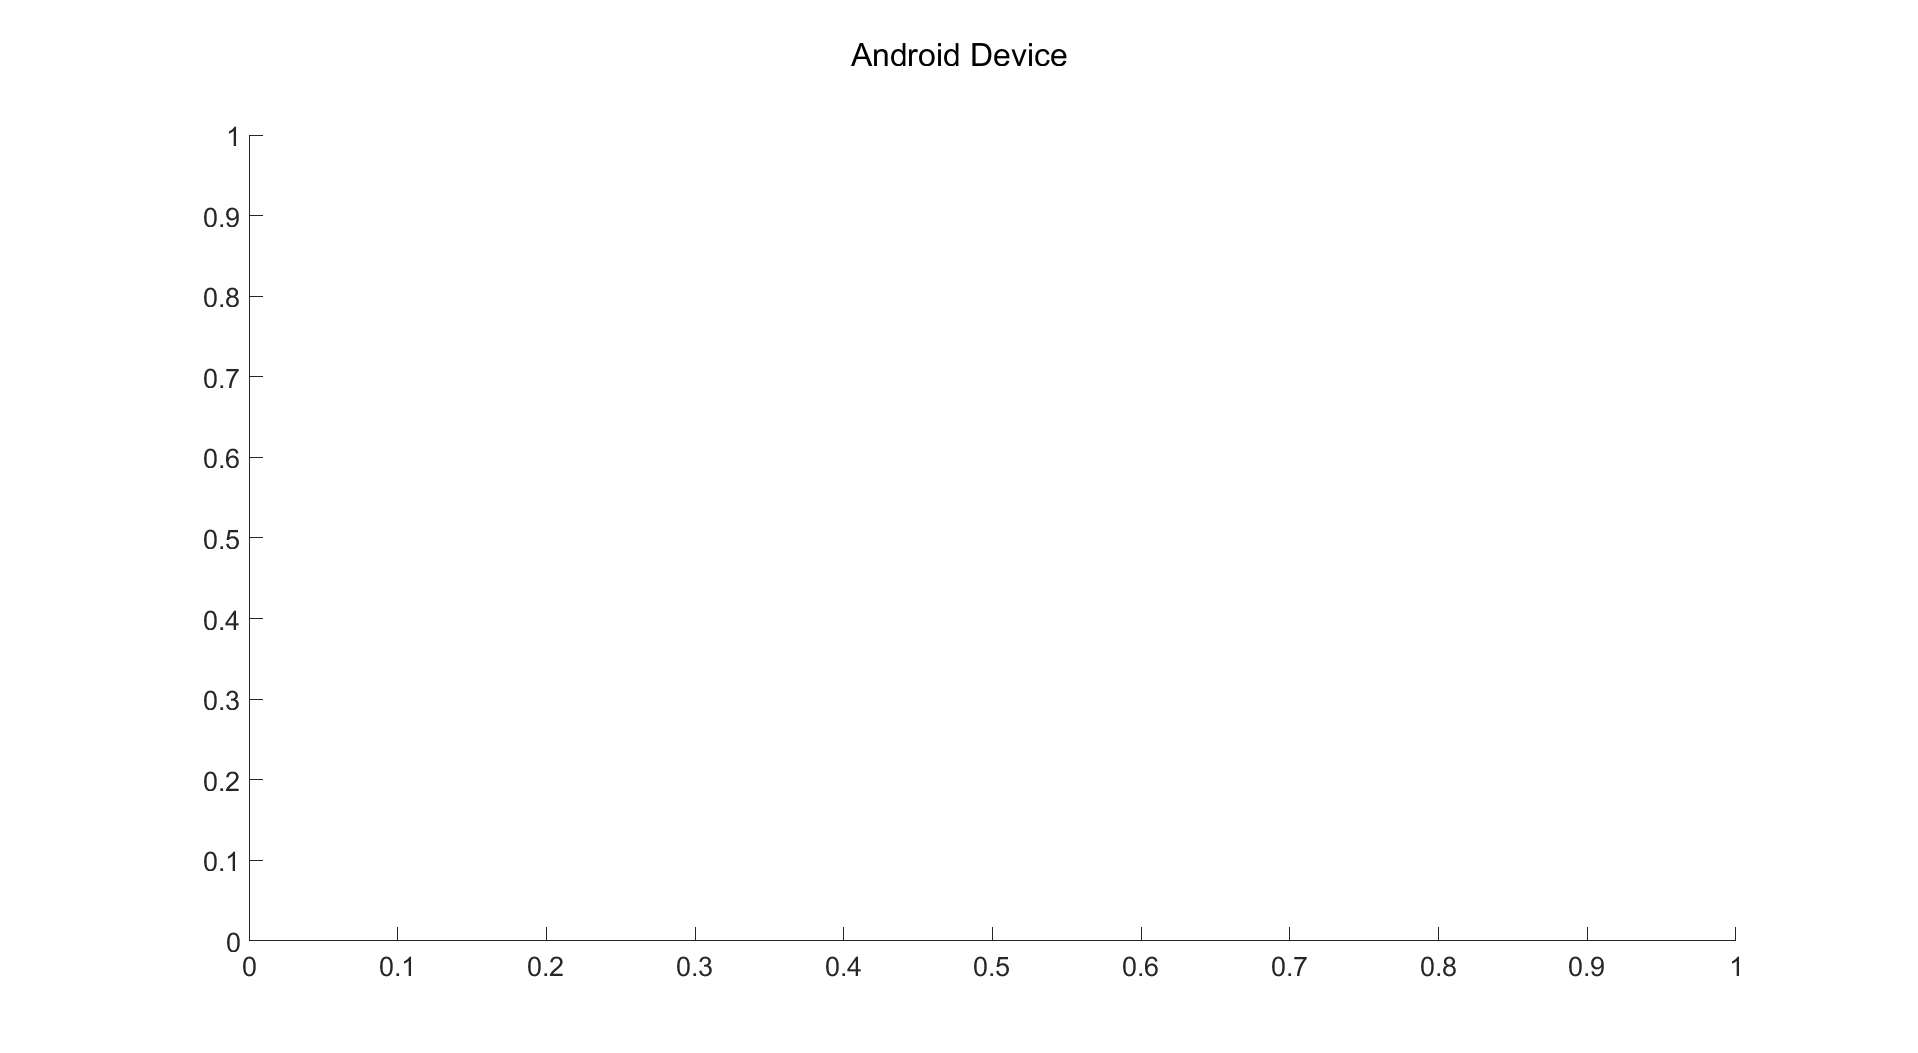

    "Android Device"    " is not yet programmed"



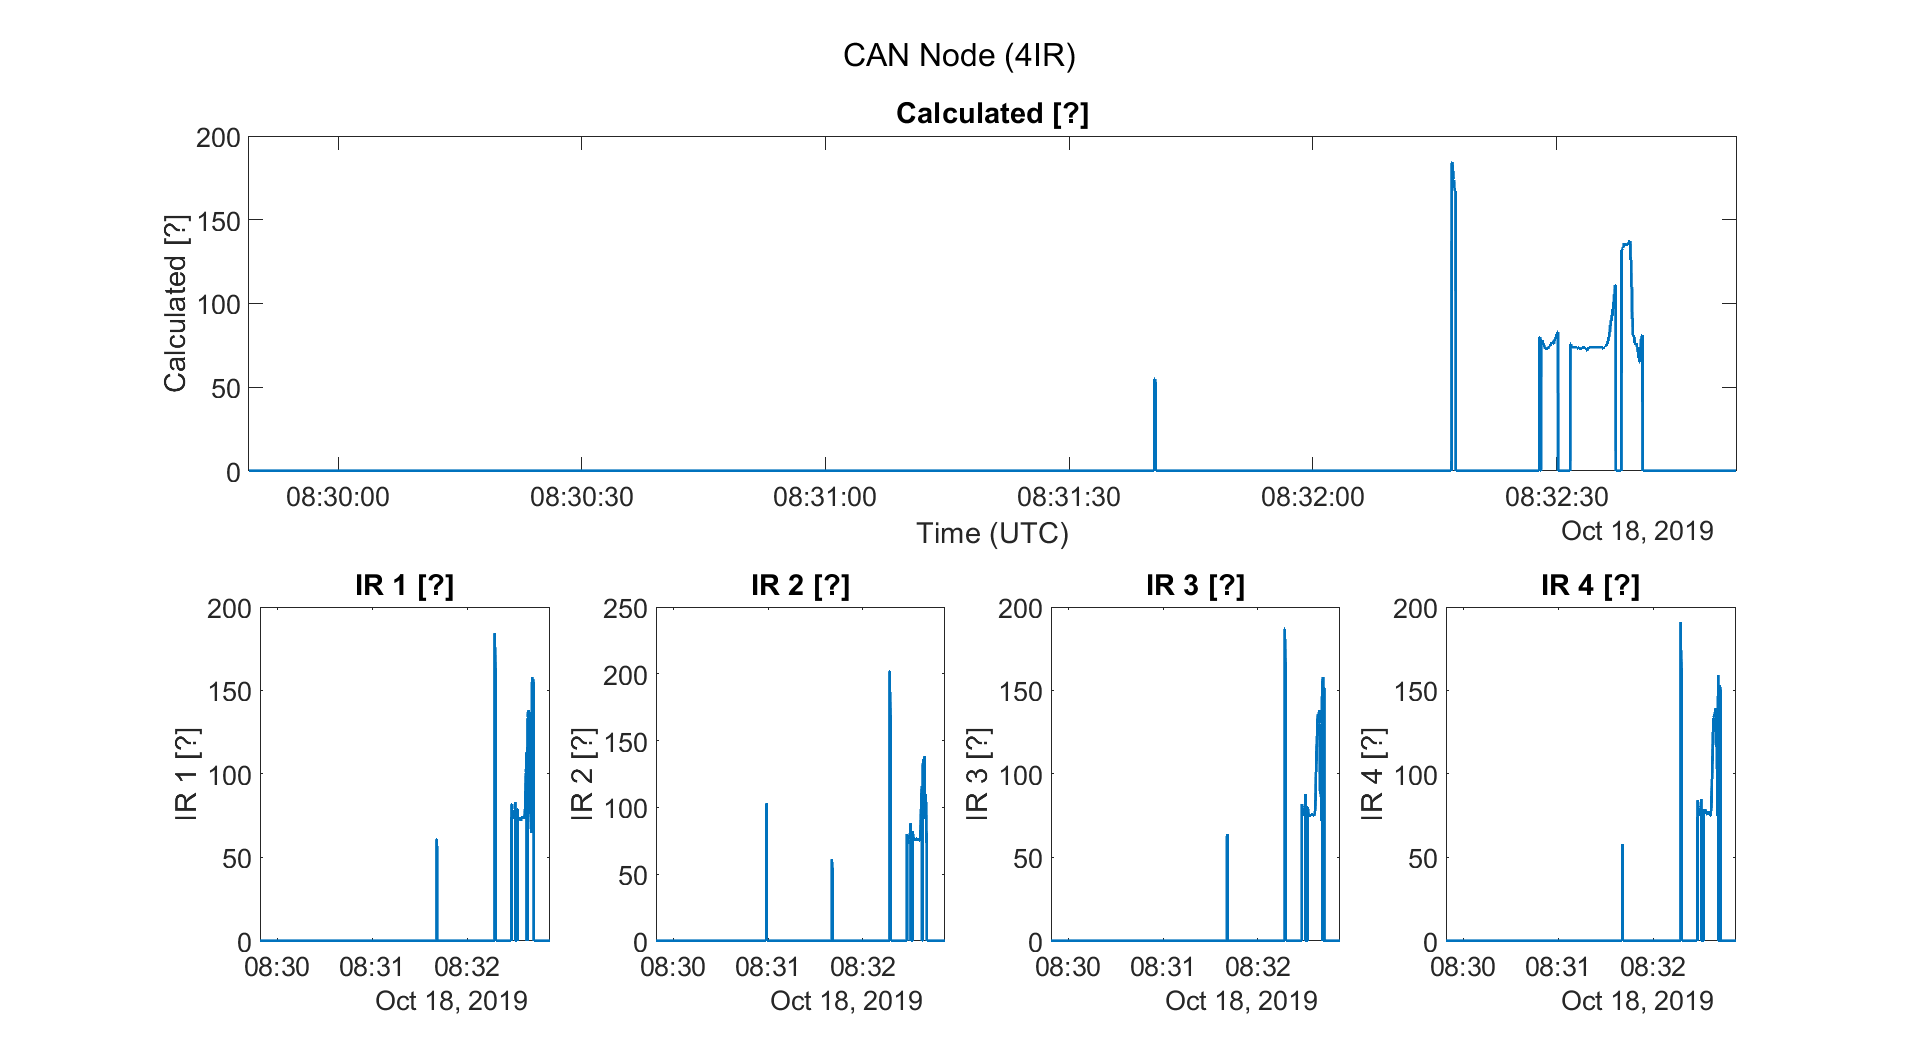

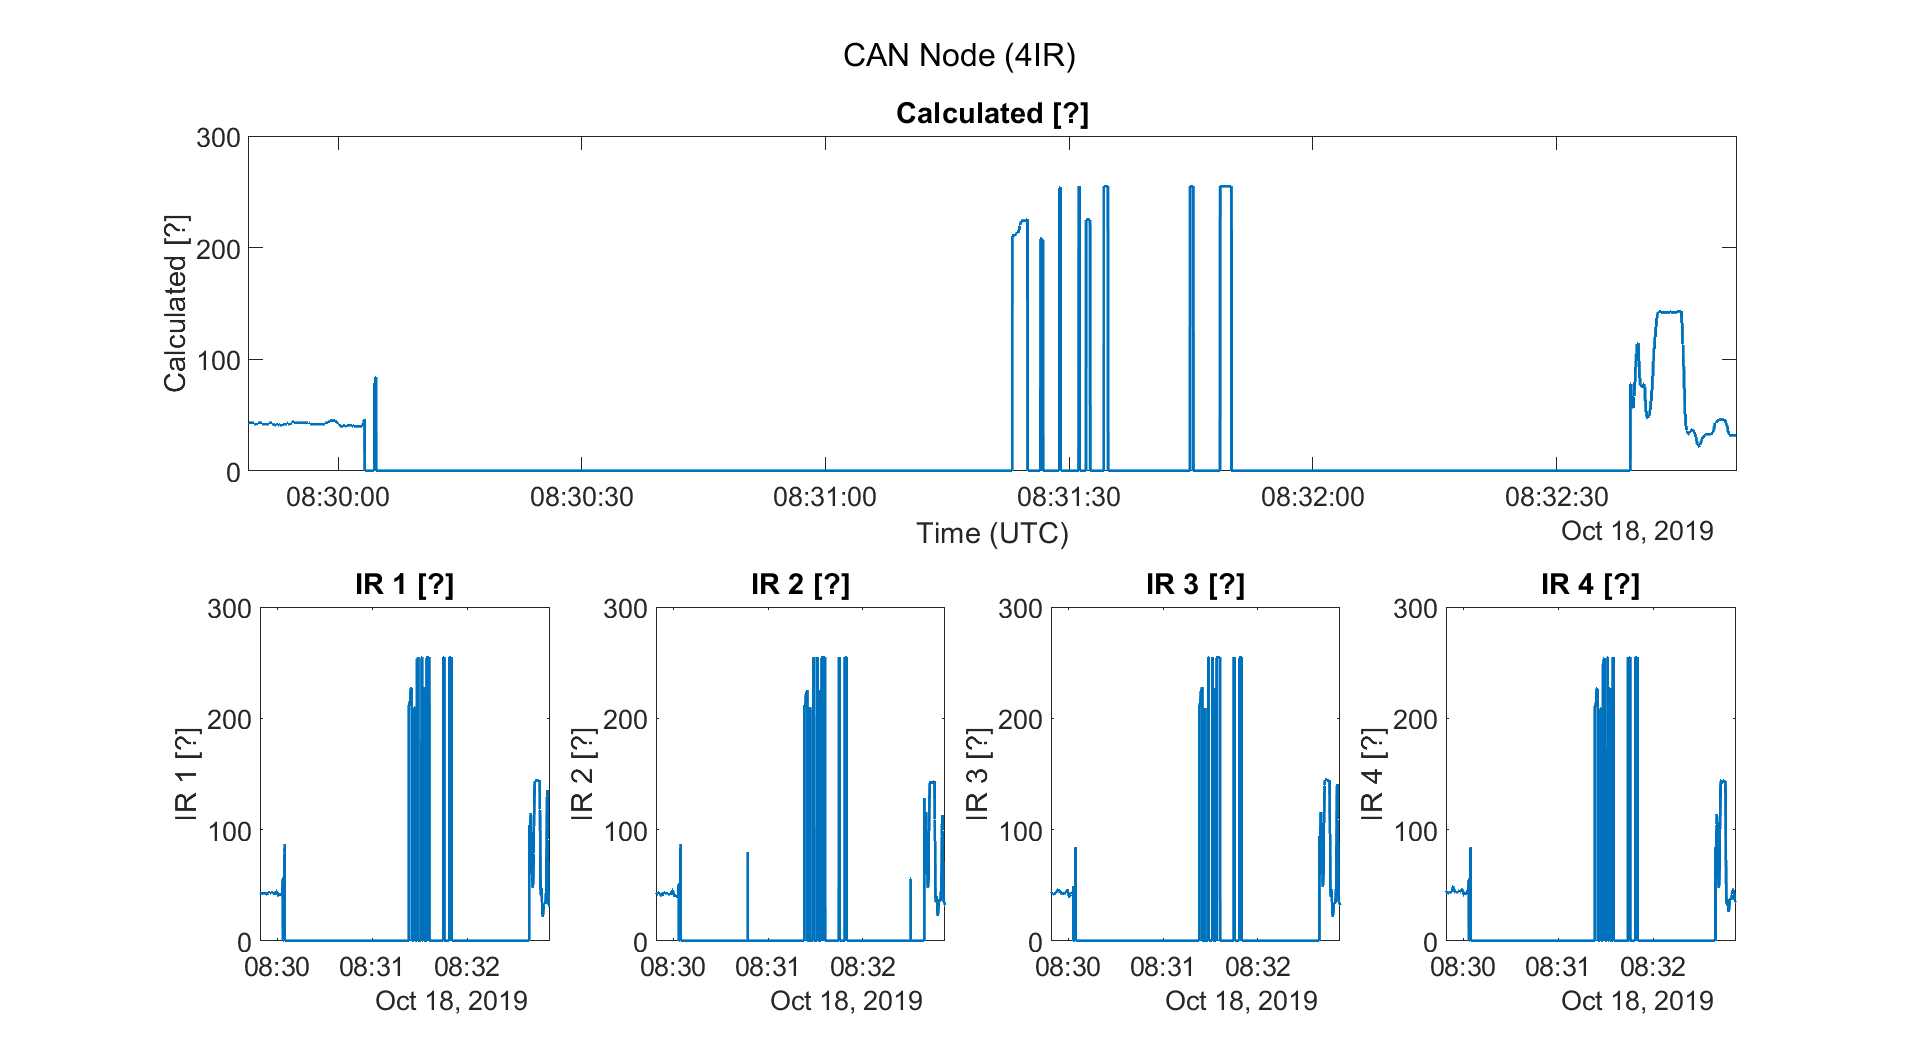

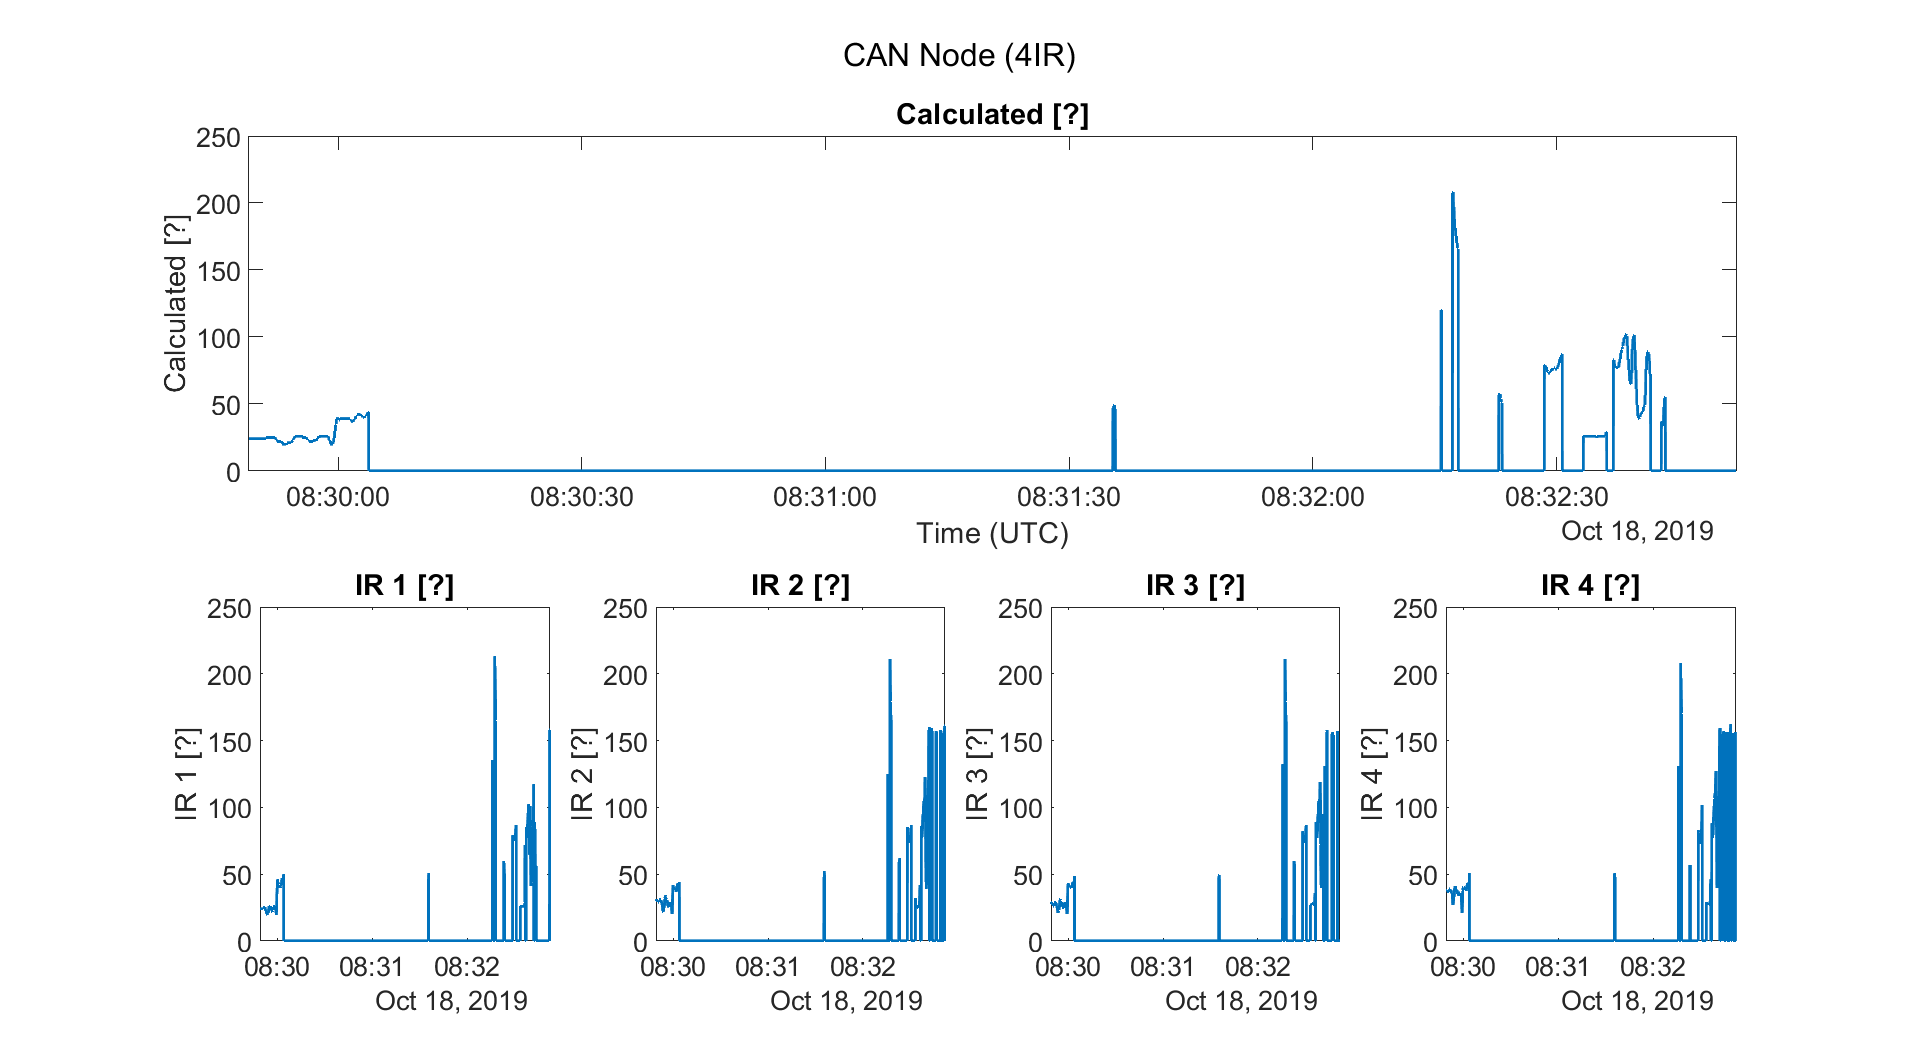

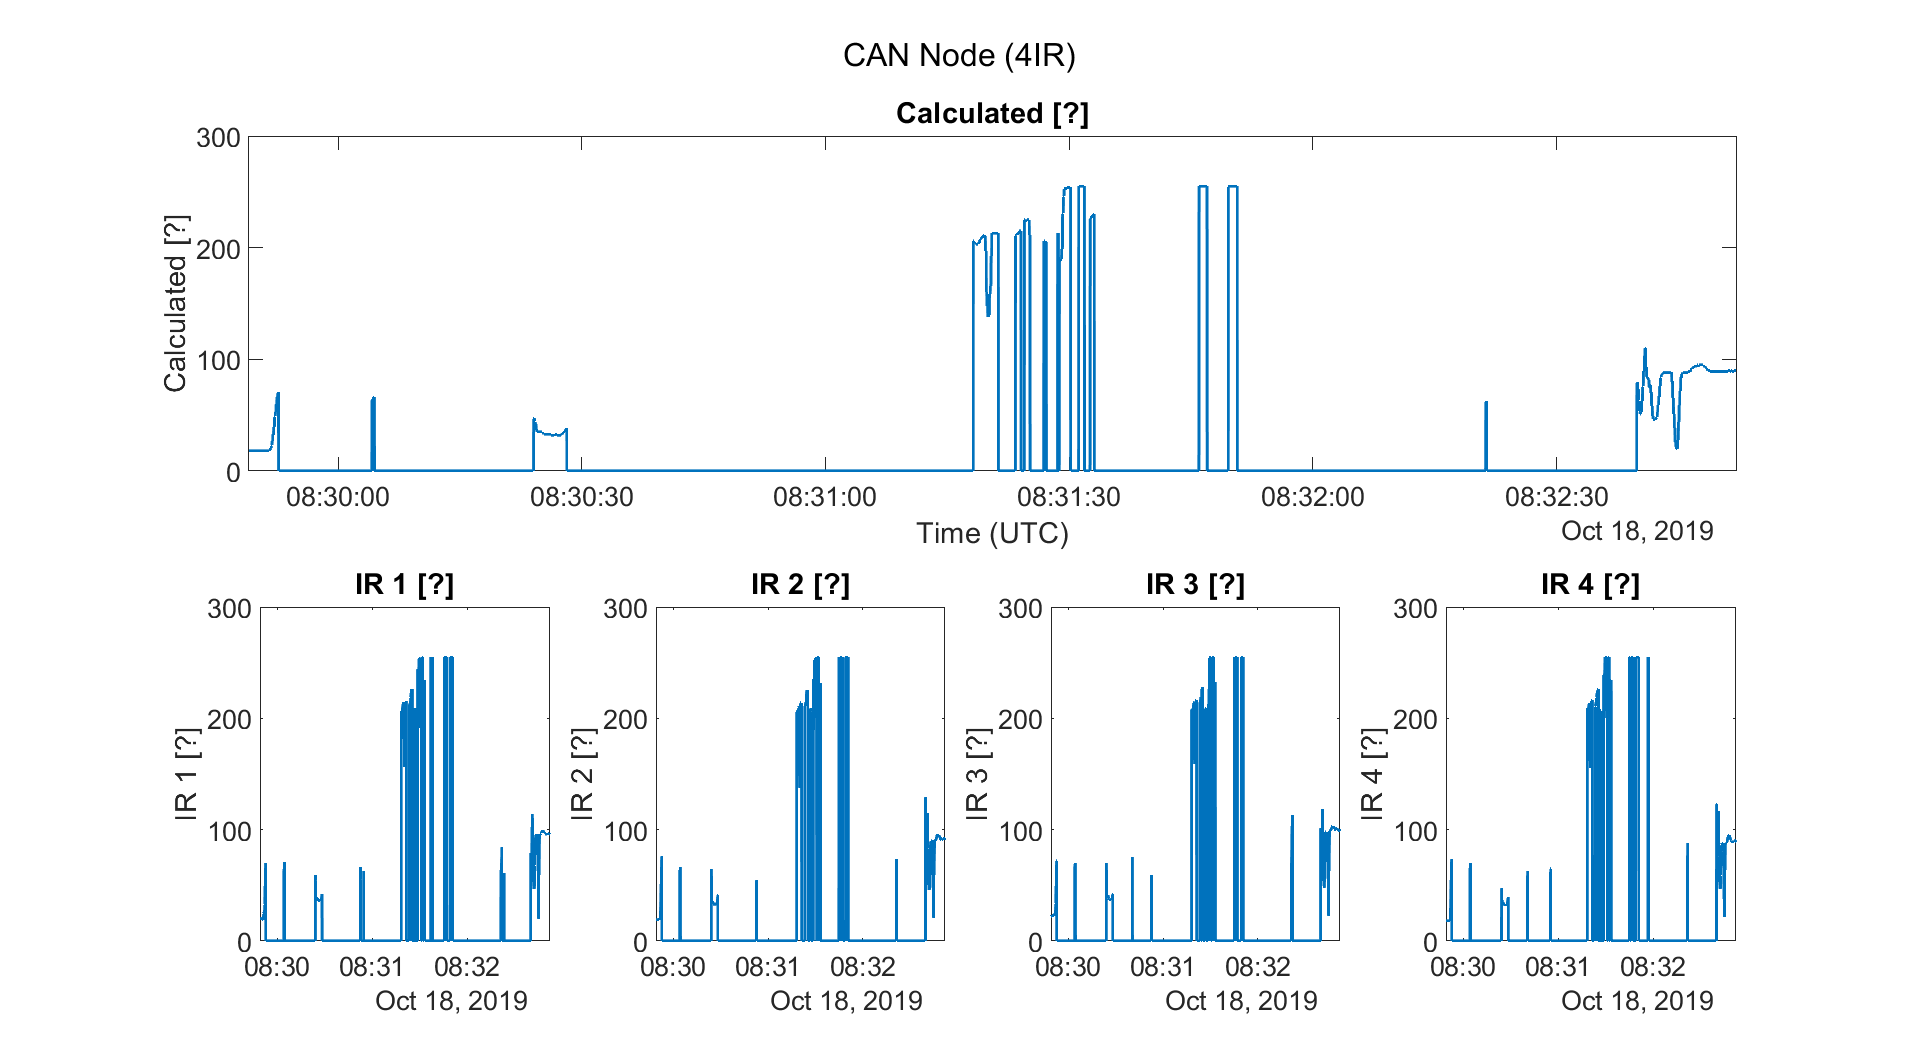


if  exist('id')
    if  m.list.count(find(m.list.id == id,1)) > 2
        m.plot_all();
    elseif m.list.count < 2
        disp("measurement contains no data")
    else
        disp("ID does not exist in database")
    end
else 
    disp("get first the data")
end

## Own analysis: type your own commands

 
time = (1:size(m.instruments(1,2).data(1,6).values,2))*0.02 + m.start_time;
figure();
fontsize = 20;
set(gca,'fontsize',fontsize) % set fontsize of the plot to 20
set(gcf, 'Position', get(0,'Screensize')); % automatic full screen
set(0, 'DefaultAxesFontSize', fontsize);
plot(time,m.instruments(1,1).data(1,2).values,'LineWidth',2)
ylabel("Turn",'fontsize',fontsize);
ax1 = gca;
yyaxis right
plot(time, m.instruments(1,2).data(1,6).values,'LineWidth',2)
xlabel('Time [s]','fontsize',fontsize);
ylabel("gz",'fontsize',fontsize);
xlim(([min(time) (max(time))]));
title("gz vs turn" ,'fontsize',fontsize);
legend(["turn","gz"]);


### Heatmaps

figure()
heatmap([m.instruments(1,1).data(1,2).values m.instruments(1,2).data(1,6).values])